# Chapter 4. Regression and Prediction

clear; close all;
dataDir = "../psds_data";
dataList = dir(dataDir);
dataList.name

ans = '.'

ans = '..'

ans = '762609057_112015_3429_airline_delay_causes.csv'

ans = 'County_Zhvi_AllHomes.csv'

ans = 'LungDisease.csv'

ans = 'airline_stats.csv'

ans = 'click_rates.csv'

ans = 'dfw_airline.csv'

ans = 'four_sessions.csv'

ans = 'full_train_set.csv'

ans = 'house_sales.csv'

ans = 'imanishi_data.csv'

ans = 'kc_tax.csv'

ans = 'lc_loans.csv'

ans = 'loan200.csv'

ans = 'loan3000.csv'

ans = 'loan_data.csv'

ans = 'loans_income.csv'

ans = 'sp500_data.csv'

ans = 'sp500_sectors.csv'

ans = 'state.csv'

ans = 'web_page_data.csv'

## Simple Linear Regression

### The regression Equation


$$Y = b_0 + b_1X$$


lung = readtable(fullfile(dataDir, "LungDisease.csv"));
head(lung)

ans = 8×2 table
    PEFR    Exposure
    ____    ________

    390        0    
    410        0    
    430        0    
    460        0    
    420        1    
    280        2    
    420        2    
    520        2    


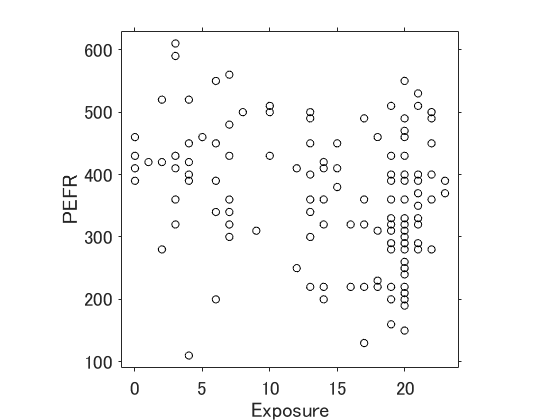

sc1 = scatter(lung.Exposure, lung.PEFR,'ok', 'SizeData', 30);
ax1 = sc1.Parent;
axis(ax1, 'square');
xlabel(ax1, "Exposure");
ylabel(ax1, "PEFR");
%
ax1.XTick = [0 5 10 15 20];
ax1.YTick = [100 200 300 400 500 600];
ax1.XLim = [-1, 24];
ax1.YLim = [90, 630];
ax1.FontSize = 14;
ax1.TickDir = "out";
ax1.Color = "none";
ax1.Box = "on";


$$\text{PEFR} = b_0 + b_1\;\text{Exposure}$$


model = fitlm(lung, "PEFR~Exposure");
disp(model);

線形回帰モデル: 
    PEFR ~ 1 + Exposure

推定された係数: 
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)     424.58     20.796     20.417    7.5122e-41
    Exposure       -4.1846      1.325    -3.1582     0.0020084


観測数: 122、誤差の自由度: 120
平方根平均二乗誤差: 101
決定係数: 0.0767、自由度調整済み決定係数: 0.069
F 統計量 - 定数モデルとの比較: 9.97、p 値は 0.00201 です


### Fitted Values and Residuals

The error is denoted by $e_i
$ and the fitted value $\hat{Y}_i$, and the residuals $\hat{e}_i$ respectively: 


$$Y_i = b_0 + b_1 X_i + e_i\\
\hat{y}_i = \hat{b}_0 + \hat{b}_1X_i\\
\hat{e}_i = Y_i-\hat{Y}_i$$


fitted and residual:

fitted = model.Fitted;
resid = model.Residuals;

Plotting them together:

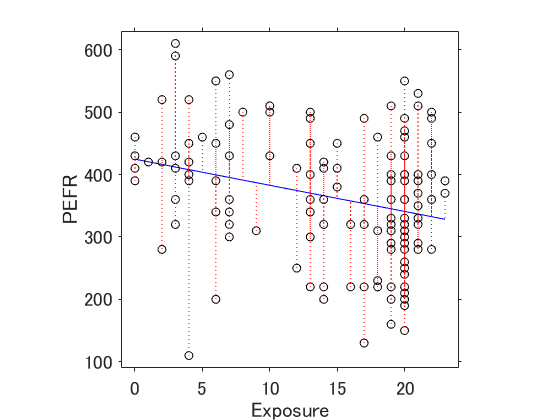

p2 = plot(lung.Exposure, fitted, '-b',...
    lung.Exposure, lung.PEFR, 'ok', "MarkerSize",6);
ax2 = p2.Parent;
axis(ax2,"square");
xlabel(ax2, "Exposure");
ylabel(ax2, "PEFR");
%
ax2.XTick = [0 5 10 15 20];
ax2.YTick = [100 200 300 400 500 600];
ax2.XLim = [-1, 24];
ax2.YLim = [90, 630];
ax2.FontSize = 14;
ax2.TickDir = "out";
ax2.Color = "none";
ax2.Box = "on";
%
hold on;
for i=1:length(lung.PEFR)
    plot([lung.Exposure(i), lung.Exposure(i)], [lung.PEFR(i), fitted(i)],'r:');
end
hold off;

### Least Squares

Residual sum of squares - RSS


$$\begin{array}{rcl}
RSS &=& \sum_{i=1}^n (Y_i-\hat{Y}_i)^2\\
       &=& \sum_{i=1}^n (Y_i-\hat{b}_0-\hat{b}_1X_i)^2
\end{array}$$


## Multiple Linear Regression


$$Y = b_0 + b_1 X_1 + \cdots + b_pX_p + e$$


The fitted values are given by:


$$\hat{Y}_i = \hat{b}_0 + \hat{b}_1 X_1 + \cdots + \hat{b}_pX_{p,i}$$


### Example: King County Housing Data

% データ読み込みオプション
opts = delimitedTextImportOptions("NumVariables", 23);

% 範囲と区切り記号の指定
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% 列名と型の指定
opts.VariableNames = ["DocumentDate", "SalePrice", "PropertyID", "PropertyType", "ym", "zhvi_px", "zhvi_idx", "AdjSalePrice", "NbrLivingUnits", "SqFtLot", "SqFtTotLiving", "SqFtFinBasement", "Bathrooms", "Bedrooms", "BldgGrade", "YrBuilt", "YrRenovated", "TrafficNoise", "LandVal", "ImpsVal", "ZipCode", "NewConstruction", "VarName23"];
opts.VariableTypes = ["double", "datetime", "double", "double", "categorical", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical"];

% ファイル レベルのプロパティを指定
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 変数プロパティを指定
opts = setvaropts(opts, ["ym", "VarName23"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "SalePrice", "InputFormat", "yyyy-MM-dd");
opts = setvaropts(opts, "zhvi_px", "InputFormat", "yyyy-MM-dd");

% データ読み込み
house = readtable(fullfile(dataDir, "house_sales.csv"), opts);
head(house(:,{'AdjSalePrice','SqFtTotLiving','SqFtLot','Bathrooms', 'Bedrooms', 'BldgGrade'}))

ans = 8×6 table
    AdjSalePrice    SqFtTotLiving    SqFtLot    Bathrooms    Bedrooms    BldgGrade
    ____________    _____________    _______    _________    ________    _________

      0.93084            9373           2            0            3          6    
      0.92923           20156           1         1452         3.75          4    
      0.97794           26036           1          900         1.75          4    
       0.9614            8618           1         1640         3.75          5    
       0.8079            8620           1            0         1.75          4    
      0.84972            1012           1            0          1.5          2    
      0.86006           34465           1            0          1.5          3    
      0.99288           14659           1          620         1.75          4    


Establish a model that drop records with missing values:

% Remove missing records from the table
house_cleaned = rmmissing(house,2);

% Model
house_lm = fitlm(house_cleaned, "AdjSalePrice ~ SqFtTotLiving + SqFtLot + Bathrooms + Bedrooms + BldgGrade");

線形回帰モデル: 
    AdjSalePrice ~ 1 + SqFtLot + SqFtTotLiving + Bathrooms + Bedrooms + BldgGrade

推定された係数: 
                      Estimate          SE         tStat        pValue  
                     ___________    __________    ________    __________

    (Intercept)          0.89595     0.0039258      228.22             0
    SqFtLot            0.0085948     0.0035214      2.4408      0.014664
    SqFtTotLiving    -2.8624e-08    1.9217e-08     -1.4895       0.13637
    Bathrooms         -6.919e-07    1.3392e-06    -0.51667       0.60539
    Bedrooms          -0.0041128     0.0008666      -4.746    2.0878e-06
    BldgGrade          0.0017617    0.00074845      2.3538       0.01859


観測数: 22689、誤差の自由度: 22683
平方根平均二乗誤差: 0.0835
決定係数: 0.00145、自由度調整済み決定係数: 0.00123
F 統計量 - 定数モデルとの比較: 6.59、p 値は 3.92e-06 です


### Assessing the Model P175

disp(house_lm);

線形回帰モデル: 
    AdjSalePrice ~ 1 + SqFtLot + SqFtTotLiving + Bathrooms + Bedrooms + BldgGrade

推定された係数: 
                      Estimate          SE         tStat        pValue  
                     ___________    __________    ________    __________

    (Intercept)          0.89595     0.0039258      228.22             0
    SqFtLot            0.0085948     0.0035214      2.4408      0.014664
    SqFtTotLiving    -2.8624e-08    1.9217e-08     -1.4895       0.13637
    Bathrooms         -6.919e-07    1.3392e-06    -0.51667       0.60539
    Bedrooms          -0.0041128     0.0008666      -4.746    2.0878e-06
    BldgGrade          0.0017617    0.00074845      2.3538       0.01859


観測数: 22689、誤差の自由度: 22683
平方根平均二乗誤差: 0.0835
決定係数: 0.00145、自由度調整済み決定係数: 0.00123
F 統計量 - 定数モデルとの比較: 6.59、p 値は 3.92e-06 です
